clear all;
close all;
clc;

set(0,'defaultaxeslinewidth',1.5);
set(0,'defaultlinelinewidth',1.5);
set(0,'DefaultAxesFontSize', 12);

load network_lstm.mat

% load minus1_TO_2_stepdata.mat
% load opp_stepdata.mat
load simulated_data1.mat

predicted_labels = predict(net, g_xup');
predicted_labels = predicted_labels';

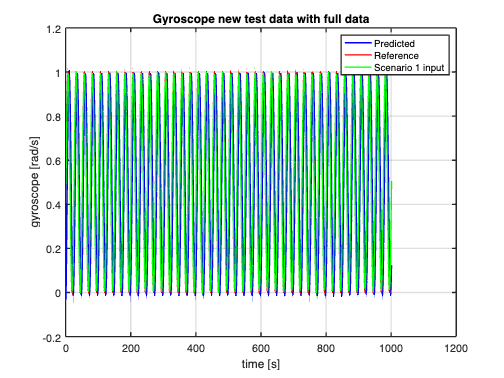

% Plots
fig1=figure;
plot(predicted_labels,'b')
hold on;
plot(gyr_ref, 'r')
plot(g_xup,'g')
grid on
hold off
xlabel('time [s]');
ylabel('gyroscope [rad/s]');
legend('Predicted','Reference','Scenario 1 input');
title('Gyroscope new test data with full data');
exportgraphics(fig1,'Gyroscope new test data with full data.png','Resolution',300);

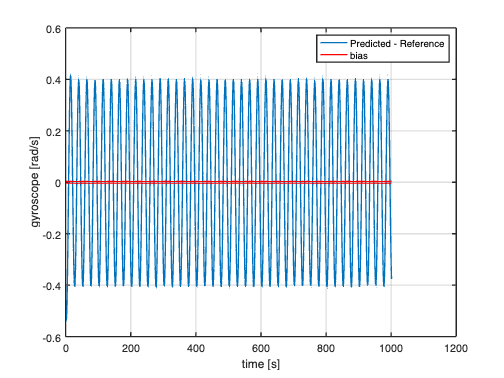


fig2=figure;
delta_g = predicted_labels-gyr_ref;
bias_gyro = repelem(bias_gyro,length(delta_g));
bias_gyro = bias_gyro';
plot(delta_g);
hold on
plot(bias_gyro,'r');
plot(-1*bias_gyro,'r');
xlabel('time [s]');
ylabel('gyroscope [rad/s]');
legend('Predicted - Reference','bias');
grid on
exportgraphics(fig2,'Difference Plot new test data.png','Resolution',300);